# Polinomios de interpolación en el análisis de temperatura

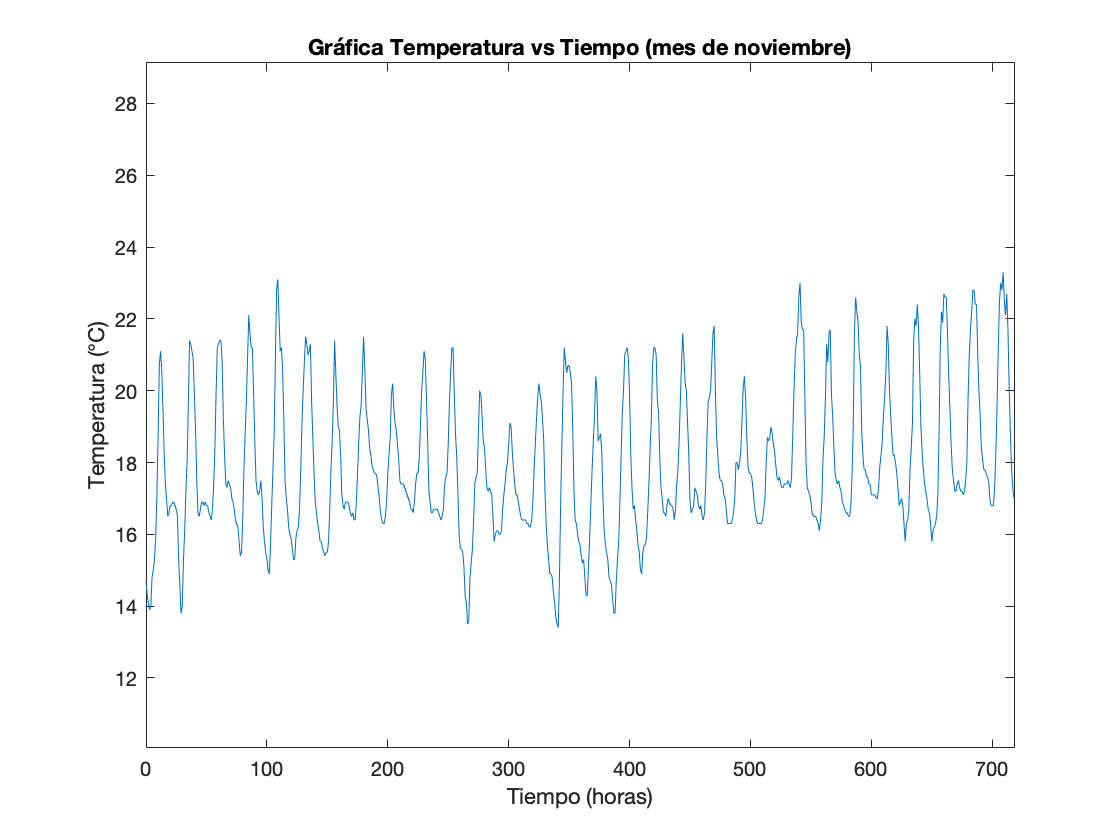

T = CargarData('data.csv');
t = (0:1:length(T)-1);

GraficaGeneral(T, t); hold off;

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')

    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
    
else
    
    hora = 12; % Se define por defecto el mediodía
    grado = 9; % Se define por defecto un polinomio de mínimos cuadrados de grado 3
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
    
end

Hora por defecto: 12


Grado de polinomio de mínimos cuadrados por defecto: 9


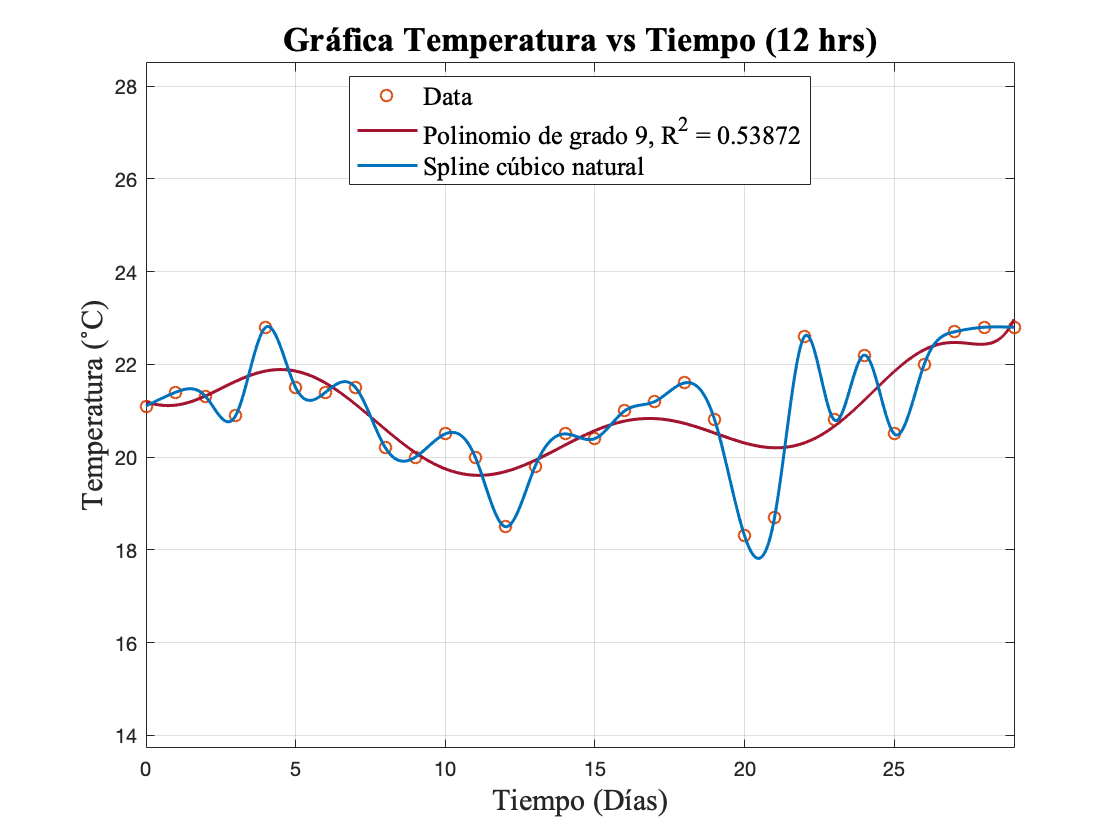

[t, T, ~, Sx] = GraficaSpline(T, hora+1, grado); 
hold off

## 
$$S_i \left(x\right)={a\left(x-x_i \right)}^3 +{b\left(x-x_i \right)}^2 +c\left(x-x_i \right)+d\;\;\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


disp(Sx)

    i     (x-x[i])             a                       b                      c               d       [x(i), x(i+1)]  
    __    ________    ____________________    ___________________    ____________________    ____    _________________

     0    "(x-0)"      -0.0234768587270079                      0       0.323476858727005    21.1    "si x ∈ [0, 1]"  
     1    "(x-1)"       -0.282615706364955    -0.0704305761810238       0.253046282545981    21.4    "si x ∈ [1, 2]"  
     2    "(x-2)"         1.25393968418682      -0.91827769527589      -0.735661988910933    21.3    "si x ∈ [2, 3]"  
     3    "(x-3)"        -2.13314303038232       2.84354135728457        1.18960167309775    20.9    "si x ∈ [3, 4]"  
     4    "(x-4)"         1.77863243734244     

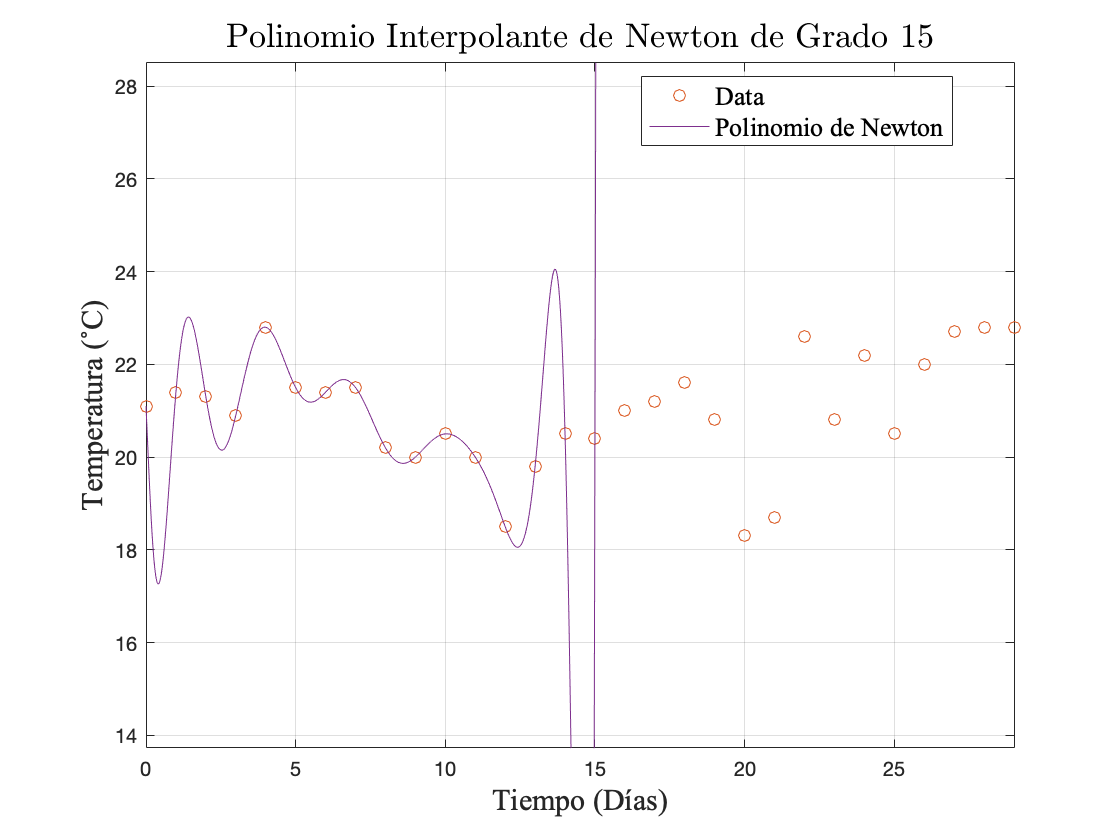

GraficaNewton(t, T, length(t)/2)